# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240209'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'solitary multi-flavor foraging'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {'14662'}; % in order of serial number list
bname_ephys = {'14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,2,0,0; 2,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209\ephys\20240209_142859.rec\14662 



trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209\ephys\20240209_142859.rec\14662\20240209_142859_merged.rec" -outputdirectory Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209\ephys\20240209_142859.rec\14662\Processed -interp 0
Using the following workspace file:  "20240209_142859_merged.trodesconf"
Exporting data...
A gap of 513 packets occured in the file. Last timestamp:  13020962 (Clock is:  "00:07:14" )
A gap of 25 packets occured in the file. Last timestamp:  13021620 (Clock is:  "00:07:14" )
A gap of 515 packets occured in the file. Last timestamp:  13026452 (Clock is:  "00:07:14" )
A gap of 14 packets occured in the file. Last timestamp:  13027051 (Clock is:  "00:07:14" )
A gap of 514 packets occured in the file. Last timestamp:  13031933 (Clock is:  "00:07:14" )
A gap of 

chanmap_file = struct with fields:
       name: '20240209_142859_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209\ephys\20240209_142859.rec\14662\Processed\20240209_142859_merged.kilosort'
       date: '14-Feb-2024 14:20:31'
      bytes: 5254
      isdir: 0
    datenum: 7.3930e+05


### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209\ephys\20240209_142859.rec\14662\Processed\20240209_142859_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  13s. Loading raw data and applying filters... 
Time 344s. Finished preprocessing 676 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.43 sec, 1 batches, 6606 spikes 
40.99 sec, 101 batches, 828907 spikes 
83.88 sec, 201 batches, 1628259 spikes 
130.06 sec, 301 batches, 2345310 spikes 
179.72 sec, 401 batches, 3067170 spikes 
232.62 sec, 501 batches, 3853030 spikes 
289.58 sec, 601 batches, 4578222 spikes 
336.45 sec, 676 batches, 5128241 spikes 


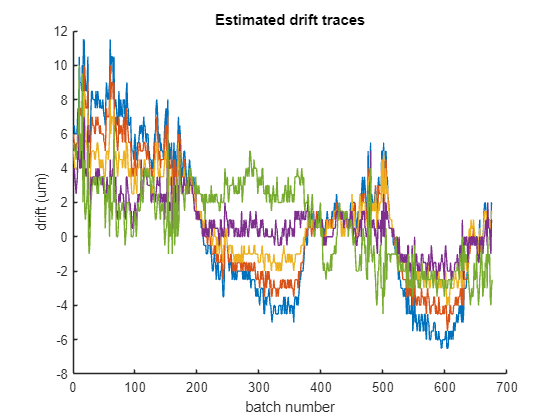

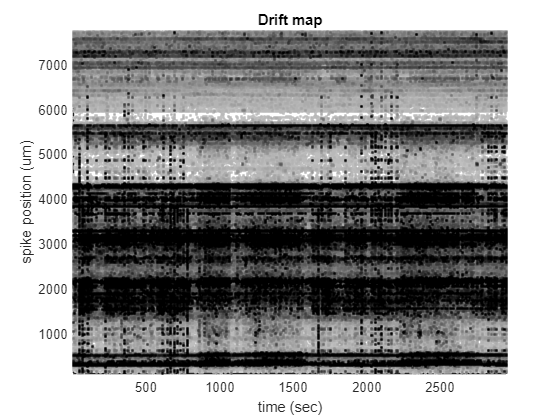

time 747.00, Shifted up/down 676 batches. 
0.67 sec, 1 batches, 10000 spikes 
58.36 sec, 101 batches, 1010000 spikes 
115.54 sec, 201 batches, 2010000 spikes 
172.18 sec, 301 batches, 3010000 spikes 
229.16 sec, 401 batches, 4010000 spikes 
286.58 sec, 501 batches, 5010000 spikes 
343.73 sec, 601 batches, 6010000 spikes 
386.69 sec, 676 batches, 6753830 spikes 
time 0.00, GROUP 1/384, units 0 
time 1.81, GROUP 6/384, units 11 
time 6.59, GROUP 11/384, units 32 
time 8.73, GROUP 16/384, units 44 
time 10.87, GROUP 21/384, units 56 
time 12.69, GROUP 26/384, units 66 
time 14.63, GROUP 31/384, units 76 
time 16.57, GROUP 36/384, units 87 
time 18.90, GROUP 41/384, units 99 
time 21.52, GROUP 46/384, units 112 
time 26.50, GROUP 51/384, units 138 
time 33.53, GROUP 56/384, units 168 
time 37.74, GROUP 61/384, units 185 
time 40.95, GROUP 66/384, units 199 
time 43.87, GROUP 71/384, units 212 
time 50.93, GROUP 76/384, units 239 
time 57.86, GROUP 81/384, units 270 
time 60.91, GROUP 86/38

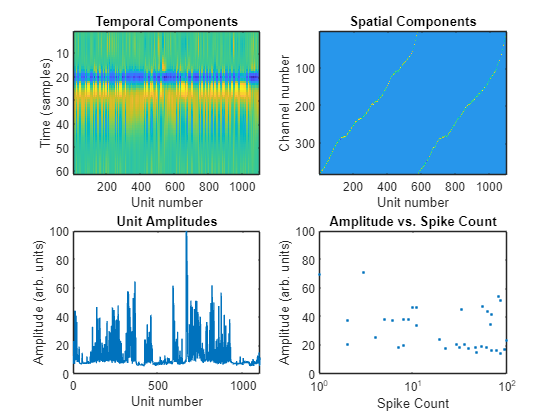

time 0.00, GROUP 1/384, units 0 
time 0.01, GROUP 6/384, units 0 
time 0.02, GROUP 11/384, units 0 
time 0.03, GROUP 16/384, units 0 
time 0.03, GROUP 21/384, units 0 
time 0.04, GROUP 26/384, units 0 
time 0.05, GROUP 31/384, units 0 
time 0.05, GROUP 36/384, units 0 
time 0.06, GROUP 41/384, units 0 
time 0.06, GROUP 46/384, units 0 
time 0.07, GROUP 51/384, units 0 
time 0.08, GROUP 56/384, units 0 
time 0.08, GROUP 61/384, units 0 
time 0.09, GROUP 66/384, units 0 
time 0.09, GROUP 71/384, units 0 
time 0.10, GROUP 76/384, units 0 
time 0.11, GROUP 81/384, units 0 
time 0.12, GROUP 86/384, units 0 
time 0.13, GROUP 91/384, units 0 
time 0.13, GROUP 96/384, units 0 
time 10.41, GROUP 101/384, units 32 
time 17.56, GROUP 106/384, units 50 
time 20.60, GROUP 111/384, units 64 
time 22.96, GROUP 116/384, units 76 
time 25.46, GROUP 121/384, units 87 
time 28.60, GROUP 126/384, units 101 
time 31.58, GROUP 131/384, units 111 
time 39.83, GROUP 136/384, units 131 
time 46.69, GROUP 141/3

ans = 172

initialized spike counts
merged 586 into 570 
merged 136 into 139 
merged 489 into 492 
merged 135 into 139 
merged 134 into 139 
merged 279 into 283 
merged 529 into 533 
merged 281 into 283 
merged 280 into 283 
merged 225 into 228 
merged 581 into 594 
merged 239 into 238 
merged 398 into 399 
merged 526 into 532 
merged 470 into 486 
merged 171 into 173 
merged 273 into 277 
merged 245 into 247 
merged 468 into 482 
merged 486 into 488 
merged 198 into 201 
merged 554 into 550 
merged 511 into 508 


ans = 157

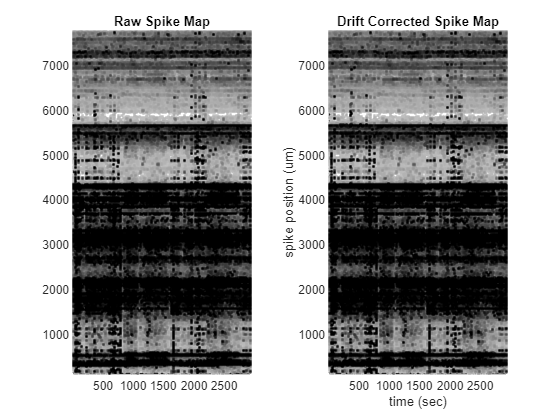

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [676×1 double]
             dshift: [676×5 double]
                st0: [5128241×6 double]
                  F: [1534×20×676 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 

path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec','14662','*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
chanmap_file = dir(fullfile(path_to_rec_dir,'Processed','*.kilosort','channelmap_probe*'));
for probeNum = 1:length(chanmap_file)
    chanmap = load(fullfile(chanmap_file(probeNum).folder,chanmap_file(probeNum).name));
    numChannels = length(chanmap.chanMap);
    runKilosort3(fullfile(path_to_rec_dir,'Processed'),'probeNum',probeNum,'numChannels',numChannels)
end


disp('kilosort finished!')

kilosort finished!


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

reward_summary = 1×4 cell array
    {'banana'}    {'banana'}    {0×0 double}    {0×0 double}


### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 28.5297
       sync_samples: 171171
       tag_duration: [28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5306 28.5304]
        tag_samples: [170306 170252 170354 170276 170291 154435 170314 162235 170214 170279]
    tag_ac_duration: [28.5305 28.5304 28.5303 28.5304 28.5304 28.5304 28.5305 28.5305 28.5304 28.5304]
     tag_ac_samples: [170289 170309 172164 171475 172088 155443 172799 163493 172589 171176]
               tags: 10

All TTLs were detected, alignment OK
Sync: Fs (network time VS interpolated): 100Hz VS 98.12 Hz
Pos Tag1: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag2: Fs (network time VS interpolated): 99.46 Hz VS 97.6 Hz


Pos Tag3: Fs (network time VS interpolated): 99.52 Hz VS 97.65 Hz


Pos Tag4: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Pos Tag5: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz


Pos Tag6: Fs (network time VS interpolated): 90.22 Hz VS 88.53 Hz


Pos Tag7: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag8: Fs (network time VS interpolated): 94.77 Hz VS 93 Hz


Pos Tag9: Fs (network time VS interpolated): 99.43 Hz VS 97.57 Hz


Pos Tag10: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Acc Tag1: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 98.69 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 98.3 Hz
Acc Tag5: Fs (network time VS interpolated): 100.5 Hz VS 98.65 Hz
Acc Tag6: Fs (network time VS interpolated): 90.8 Hz VS 89.11 Hz
Acc Tag7: Fs (network time VS interpolated): 100.9 Hz VS 99.06 Hz
Acc Tag8: Fs (network time VS interpolated): 95.51 Hz VS 93.72 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 98.94 Hz
Acc Tag10: Fs (network time VS interpolated): 100 Hz VS 98.13 Hz


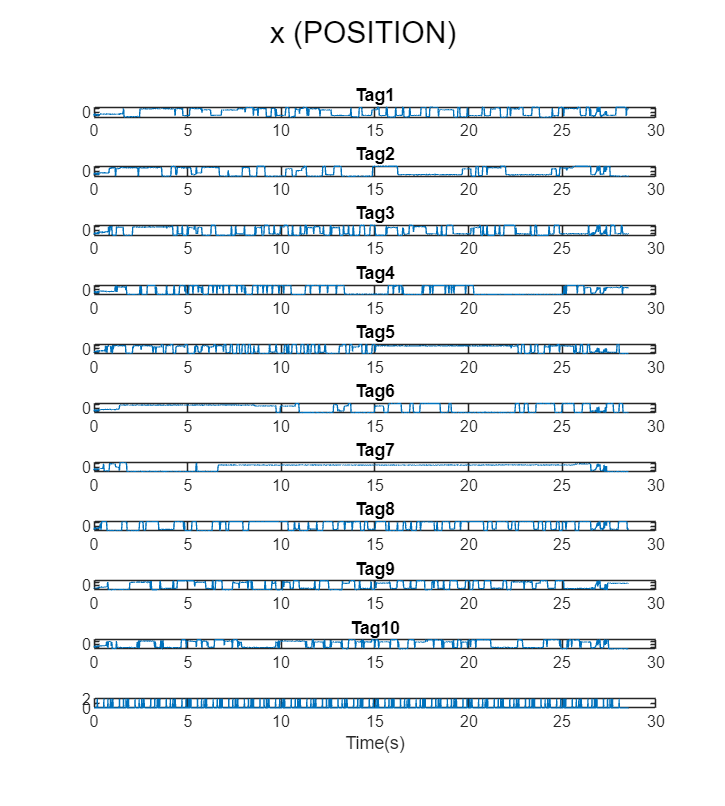

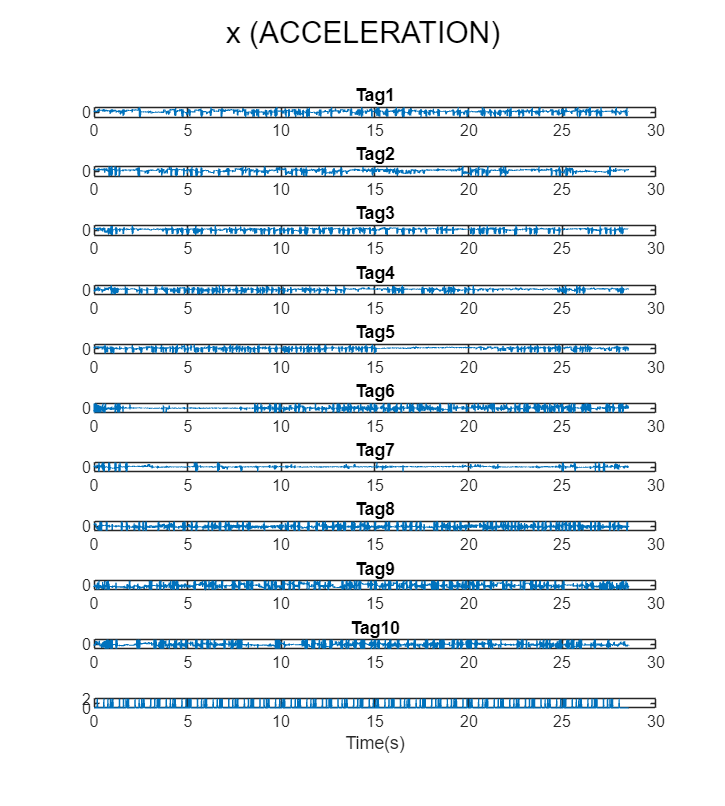

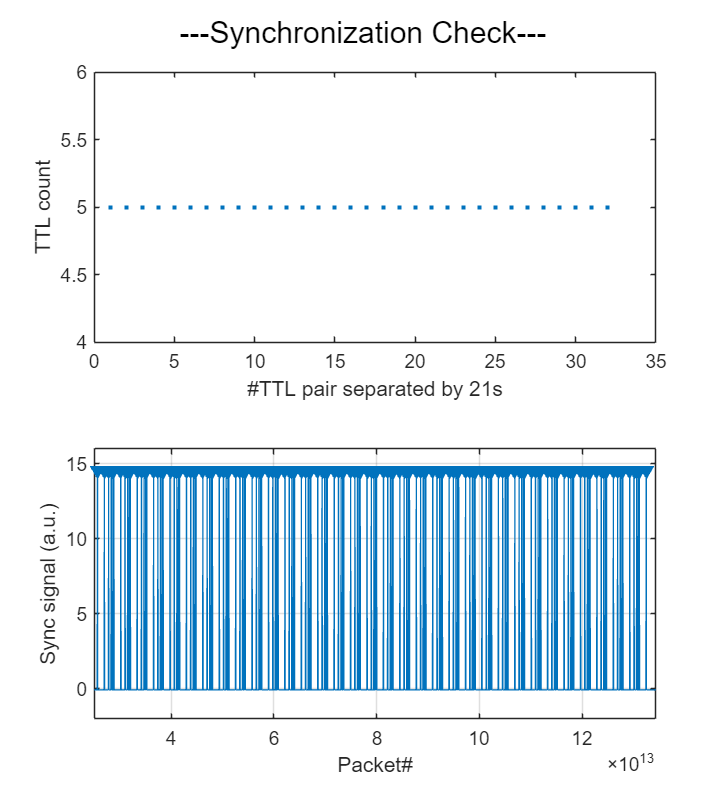

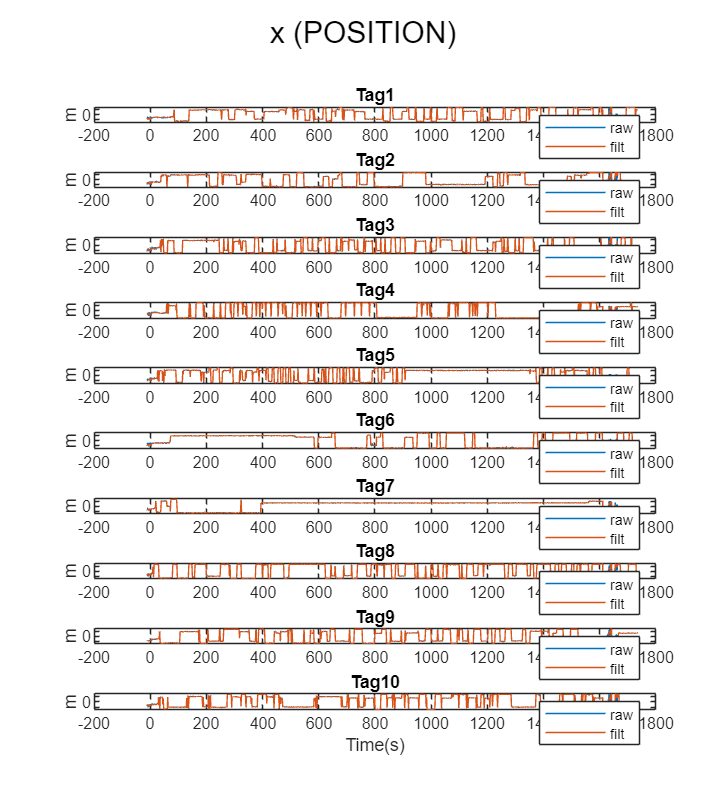

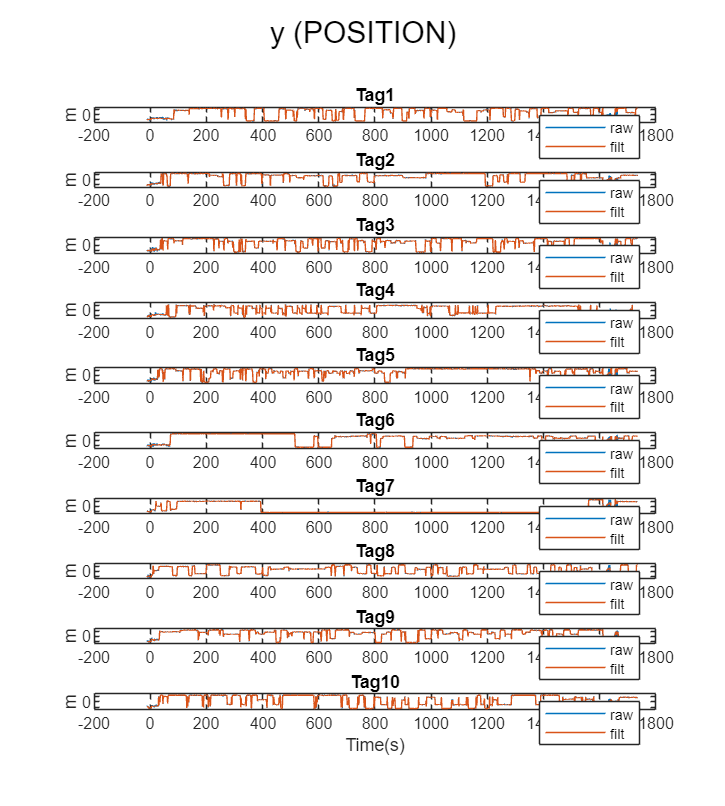

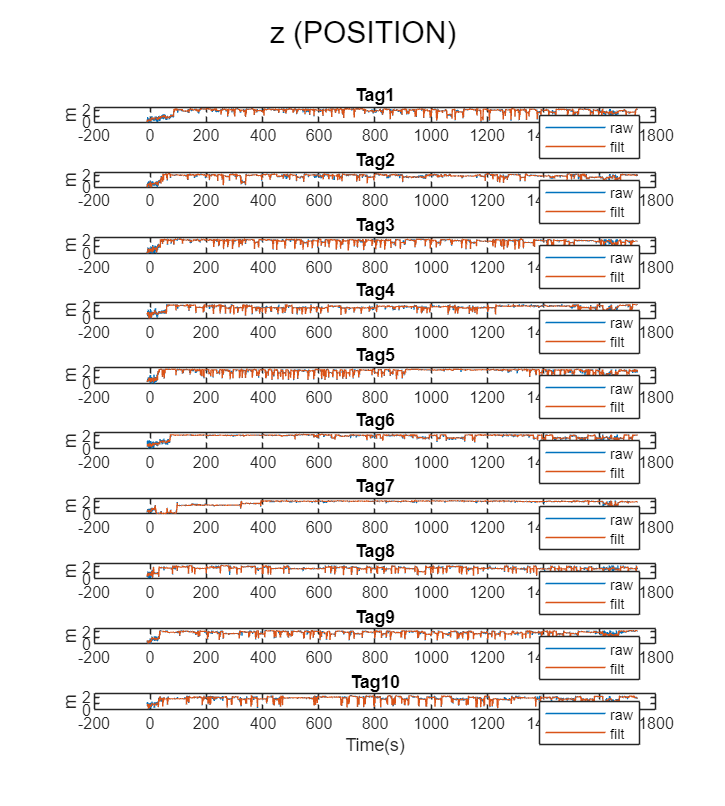

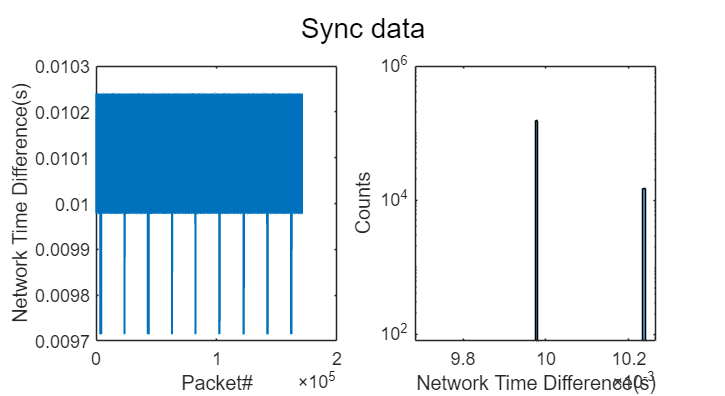

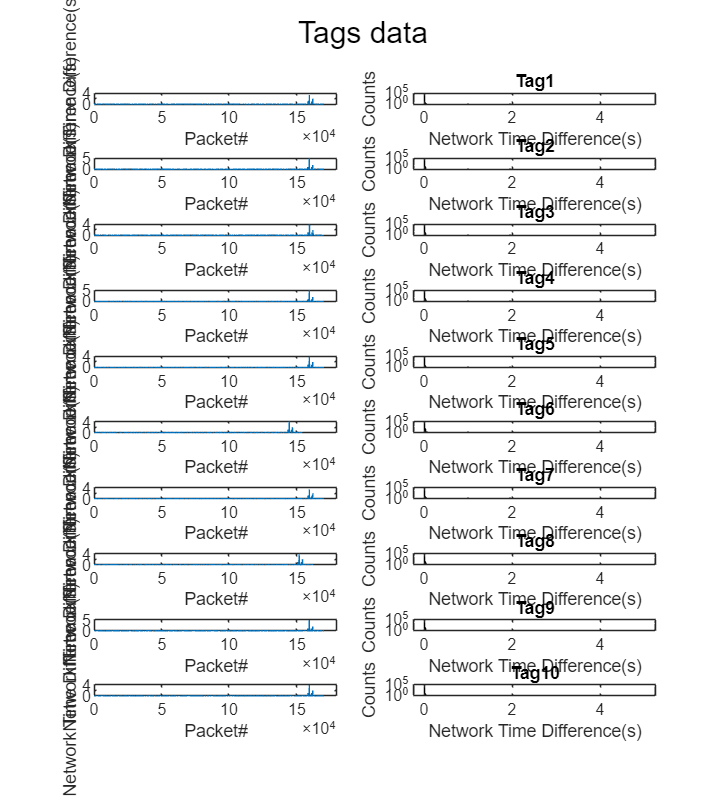

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

...Processing Ciholas Data...


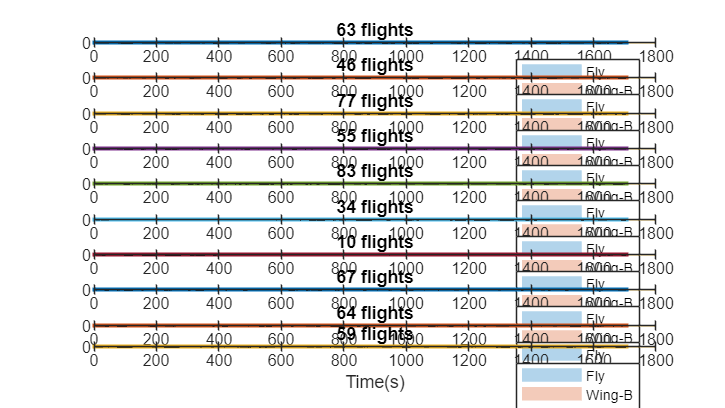

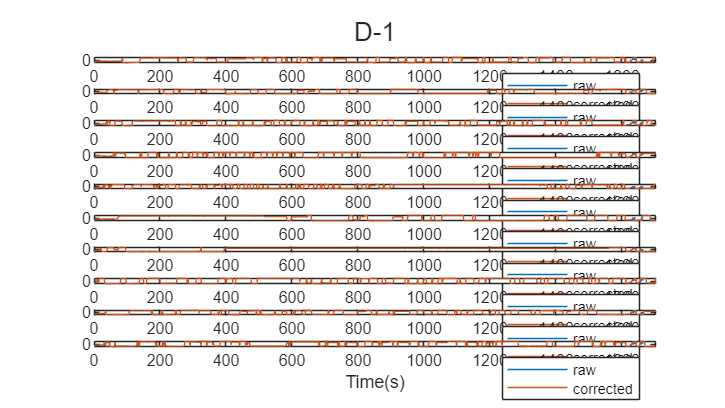

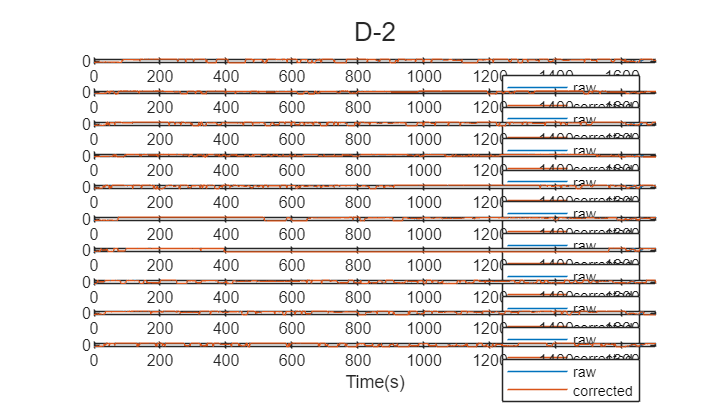

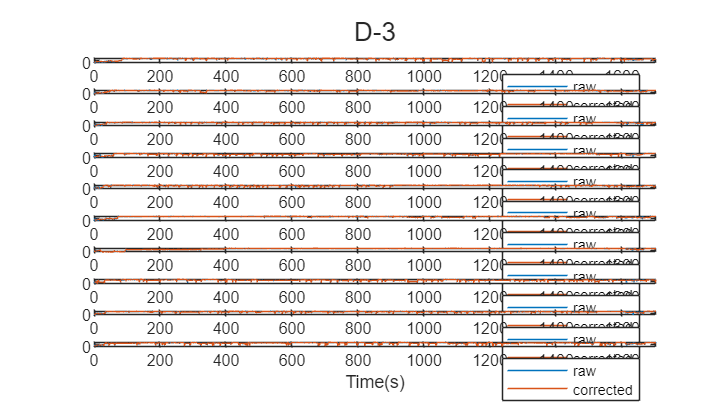

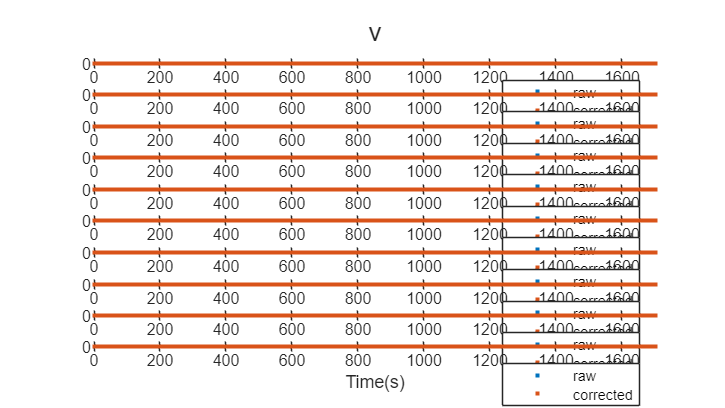

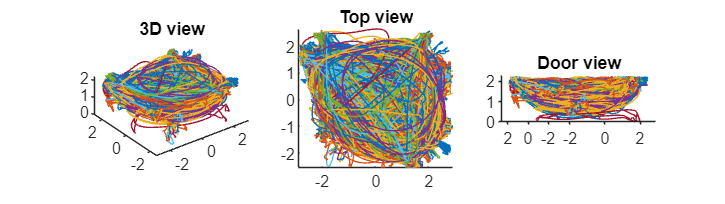

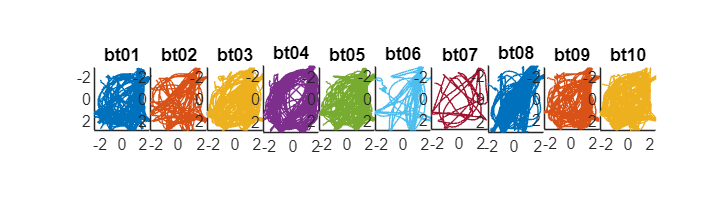

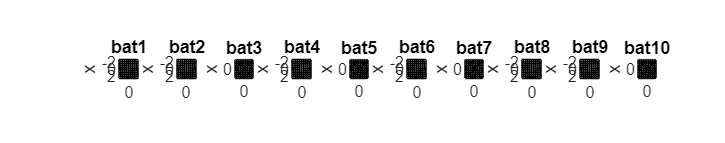

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);